%pull in the data 
clear; clc;

S = load('/Users/yuanyang/Downloads/short_term_foshan_train_val.mat');

data_mobile = S.data_mobile;
data_static = S.data_static;

% Inspect the first static sensor table
T = data_static{1};
head(T)

           time             hmd     spd     tmp     pm2d5     lat       lon  
    ___________________    _____    ____    ____    _____    ______    ______

    2018-10-08 00:00:00     37.2    0.36    34.7       58    23.046    113.16
    2018-10-08 00:00:03     37.2    0.21    34.7       56    23.046    113.16
    2018-10-08 00:00:06     37.2    0.09    34.7       56    23.046    113.16
    2018-10-08 00:00:09    37.13    0.36    34.7    55.33    23.046    113.16
    2018-10-08 00:00:12     37.1    0.14    34.7       56    23.046    113.16
    2018-10-08 00:00:15    37.03    0.18    34.7       57    23.046    113.16
    2018-10-08 00:00:19    37.03    0.12    34.7       57    23.046    113.16
    2018-10-08 00:00:22    37.07    0.24    34.7       57  

summary(T)


T: 229821×7 table

Variables:

    time: datetime
    hmd: double
    spd: double
    tmp: double
    pm2d5: double
    lat: double
    lon: double

Statistics for applicable variables:

             NumMissing              Min                      Median                       Max                       Mean                   Std      

    time         0           2018-10-08 00:00:00        2018-10-12 00:02:27        2018-10-15 23:59:58        2018-10-12 00:00:01        55:26:29    
    hmd          0                       36.7000                    44.2000                    59.6000                    46.0999            5.5450  
    spd          0                        0.0200                     0.2

% Sort records by time
T = sortrows(T, 'time');

% Check missing values
disp('Missing values per column:');

Missing values per column:


disp(varfun(@(x) sum(ismissing(x)), T));

    Fun_time    Fun_hmd    Fun_spd    Fun_tmp    Fun_pm2d5    Fun_lat    Fun_lon
    ________    _______    _______    _______    _________    _______    _______

       0           0          0          0           0           0          0   




% Check sampling intervals
dt = seconds(diff(T.time));
typicalInterval = median(dt, 'omitnan');

fprintf('Median interval: %.1f seconds\n', typicalInterval);

Median interval: 3.0 seconds


fprintf('Largest interval: %.1f seconds\n', max(dt));

Largest interval: 75.0 seconds



% Flag longer intervals for inspection, not automatic removal
gapIndex = find(dt > 2 * typicalInterval);

gaps = table(T.time(gapIndex), T.time(gapIndex + 1), ...
    dt(gapIndex), ...
    'VariableNames', {'BeforeGap', 'AfterGap', 'GapSeconds'});

disp('Ten longest gaps:');

Ten longest gaps:


gaps = sortrows(gaps, 'GapSeconds', 'descend');
disp(gaps(1:min(10, height(gaps)), :));

         BeforeGap              AfterGap          GapSeconds
    ___________________    ___________________    __________

    2018-10-11 14:55:25    2018-10-11 14:56:40        75    
    2018-10-11 14:59:28    2018-10-11 15:00:34        66    
    2018-10-11 15:31:28    2018-10-11 15:32:19        51    
    2018-10-11 15:16:46    2018-10-11 15:17:34        48    
    2018-10-11 15:21:16    2018-10-11 15:22:04        48    
    2018-10-11 15:25:16    2018-10-11 15:26:01        45    




% Inspect the ten highest PM2.5 readings
valid = ~isnan(T.pm2d5) & ~isinf(T.pm2d5);
highest = sortrows(T(valid, :), 'pm2d5', 'descend');

disp('Ten highest PM2.5 readings:');

Ten highest PM2.5 readings:


disp(highest(1:min(10, height(highest)), {'time', 'pm2d5'}));

           time            pm2d5 
    ___________________    ______

    2018-10-08 21:38:18       161
    2018-10-08 21:38:15    160.33
    2018-10-08 21:38:21       160
    2018-10-08 21:38:12       158
    2018-10-08 21:38:09    156.67
    2018-10-08 21:38:24    155.67
    2018-10-08 21:38:27       155
    2018-10-08 21:38:30    152.33
    2018-10-08 21:38:06       149
    2018-10-08 21:38:03    148.67



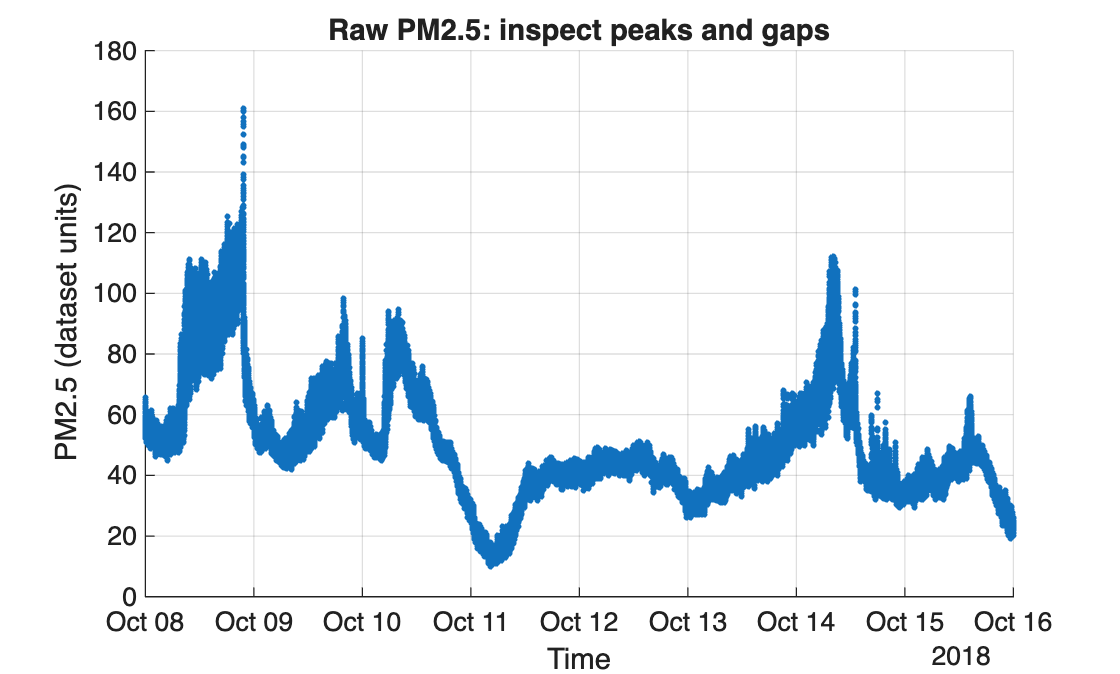


% Plot PM2.5 without connecting across gaps
figure;
scatter(T.time, T.pm2d5, 5, 'filled');
xlabel('Time');
ylabel('PM2.5 (dataset units)');
title('Raw PM2.5: inspect peaks and gaps');
grid on;

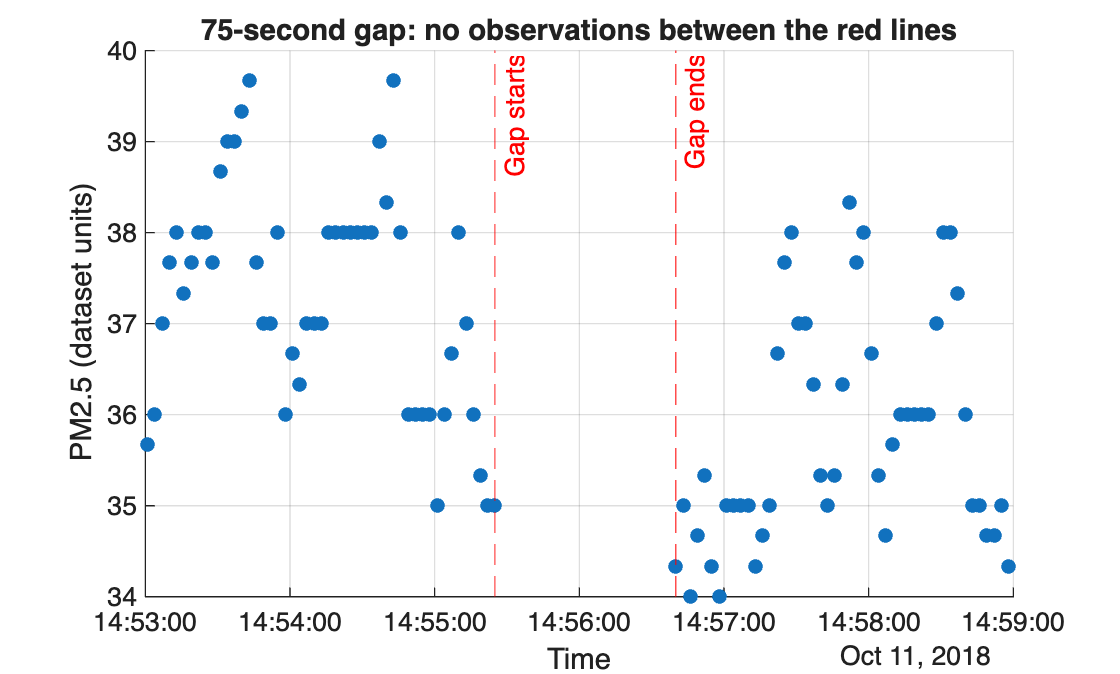

startTime = datetime(2018,10,11,14,53,0);
endTime   = datetime(2018,10,11,14,59,0);

gapStart = datetime(2018,10,11,14,55,25);
gapEnd   = datetime(2018,10,11,14,56,40);

idx = T.time >= startTime & T.time <= endTime;

figure;
scatter(T.time(idx), T.pm2d5(idx), 30, 'filled');
hold on;

xline(gapStart, '--r', 'Gap starts');
xline(gapEnd, '--r', 'Gap ends');

xlim([startTime endTime]);
xtickformat('HH:mm:ss');
xlabel('Time');
ylabel('PM2.5 (dataset units)');
title('75-second gap: no observations between the red lines');
grid on;

S = load('/Users/yuanyang/Downloads/short_term_foshan_train_val.mat', ...
    'data_static', 'data_mobile');

targetStart = datetime(2018,10,11,14,55,25);
targetEnd   = datetime(2018,10,11,14,56,40);
gapThreshold = 6; % Flag intervals longer than 6 seconds

groups = {'data_static', 'data_mobile'};

results = table('Size', [0 5], ...
    'VariableTypes', {'string','datetime','datetime','double','double'}, ...
    'VariableNames', {'SensorTable','BeforeGap','AfterGap', ...
    'GapSeconds','OverlapSeconds'});

for g = 1:numel(groups)
    tables = S.(groups{g});

    for i = 1:numel(tables)
        t = tables{i}.time(:);
        t = sort(t(~isnat(t)));

        if numel(t) < 2
            continue;
        end

        % Match the timezone stored in this table, if specified.
        a = targetStart;
        b = targetEnd;
        a.TimeZone = t.TimeZone;
        b.TimeZone = t.TimeZone;

        gapStart = t(1:end-1);
        gapEnd   = t(2:end);
        gapSeconds = seconds(gapEnd - gapStart);

        % Select long intervals that overlap the target period.
        matches = find(gapSeconds > gapThreshold & ...
            gapStart < b & gapEnd > a);

        label = sprintf('%s{%d}', groups{g}, i);

        if isempty(matches)
            if t(1) > a || t(end) < b
                fprintf('%s: table does not cover the full target period.\n', ...
                    label);
            else
                fprintf('%s: no interval > 6 seconds overlaps this period.\n', ...
                    label);
            end
        else
            for j = matches'
                overlapStart = max(gapStart(j), a);
                overlapEnd = min(gapEnd(j), b);
                overlapSeconds = seconds(overlapEnd - overlapStart);

                newRow = table(string(label), gapStart(j), gapEnd(j), ...
                    gapSeconds(j), overlapSeconds, ...
                    'VariableNames', results.Properties.VariableNames);

                results = [results; newRow];
            end
        end
    end
end

disp('Long intervals overlapping the target period:');

Long intervals overlapping the target period:


clear; close all; clc;

S = load('/Users/yuanyang/Downloads/short_term_foshan_train_val.mat', ...
    'data_mobile');

n = numel(S.data_mobile);
colors = lines(n);

% Do not connect observations separated by more than 60 seconds.
% This is an exploratory plotting setting, not a confirmed fault threshold.
maxGapSeconds = 60;

sensor = strings(n,1);
records = zeros(n,1);
observedDistanceKm = zeros(n,1);
eastWestSpanKm = zeros(n,1);
northSouthSpanKm = zeros(n,1);
excludedIntervals = zeros(n,1);
routes = cell(n,1);

%% Prepare routes and calculate distances
for i = 1:n
    T = S.data_mobile{i};

    valid = ~isnat(T.time) & ...
        isfinite(T.lat) & isfinite(T.lon) & ...
        abs(T.lat) <= 90 & abs(T.lon) <= 180 & ...
        ~(T.lat == 0 & T.lon == 0);

    T = sortrows(T(valid,:), 'time');

    lat = T.lat(:);
    lon = T.lon(:);
    t = T.time(:);

    assert(numel(t) >= 2, 'Too few valid records in mobile table %d.', i);

    dt = seconds(diff(t));

    % Haversine distance between consecutive GPS observations
    latRad = deg2rad(lat);
    lonRad = deg2rad(lon);

    dlat = diff(latRad);
    dlon = diff(lonRad);

    a = sin(dlat/2).^2 + ...
        cos(latRad(1:end-1)) .* cos(latRad(2:end)) .* ...
        sin(dlon/2).^2;
    a = min(1, max(0, a));

    stepKm = 2 * 6371 * atan2(sqrt(a), sqrt(1-a));

    connected = dt > 0 & dt <= maxGapSeconds;

    sensor(i) = "Mobile " + i;
    records(i) = height(T);
    observedDistanceKm(i) = sum(stepKm(connected));

    % Approximate dimensions of the GPS bounding box
    eastWestSpanKm(i) = 6371 * cosd(mean(lat)) * ...
        deg2rad(max(lon) - min(lon));

    northSouthSpanKm(i) = 6371 * ...
        deg2rad(max(lat) - min(lat));

    excludedIntervals(i) = sum(~connected);

    % Insert NaNs to break plotted lines across gaps.
    % Preserve the first point after each gap.
    plotLat = NaN(2*numel(lat)-1, 1);
    plotLon = NaN(2*numel(lon)-1, 1);

    plotLat(1:2:end) = lat;
    plotLon(1:2:end) = lon;

    mid = find(connected);
    plotLat(2*mid) = lat(mid);
    plotLon(2*mid) = lon(mid);

    routes{i} = struct('lat',lat, 'lon',lon, ...
        'plotLat',plotLat, 'plotLon',plotLon);
end

%% Summary table
summaryTable = table(sensor, records, observedDistanceKm, ...
    eastWestSpanKm, northSouthSpanKm, excludedIntervals);

disp(summaryTable);

      sensor       records      observedDistanceKm    eastWestSpanKm    northSouthSpanKm    excludedIntervals
    __________    __________    __________________    ______________    ________________    _________________

    "Mobile 1"         99944          1213.8              21.567             19.186                 81       
    "Mobile 2"     1.405e+05          594.95              5.4973              5.562                 86       
    "Mobile 3"    1.2076e+05          1117.3              9.3136             5.5686                 67       
    "Mobile 4"    1.2042e+05          775.61              8.7691             15.829                 55       
    "Mobile 5"    1.3806e+05          1398.1              16.055             10.232                127       
    "Mobile 6"     1.587e

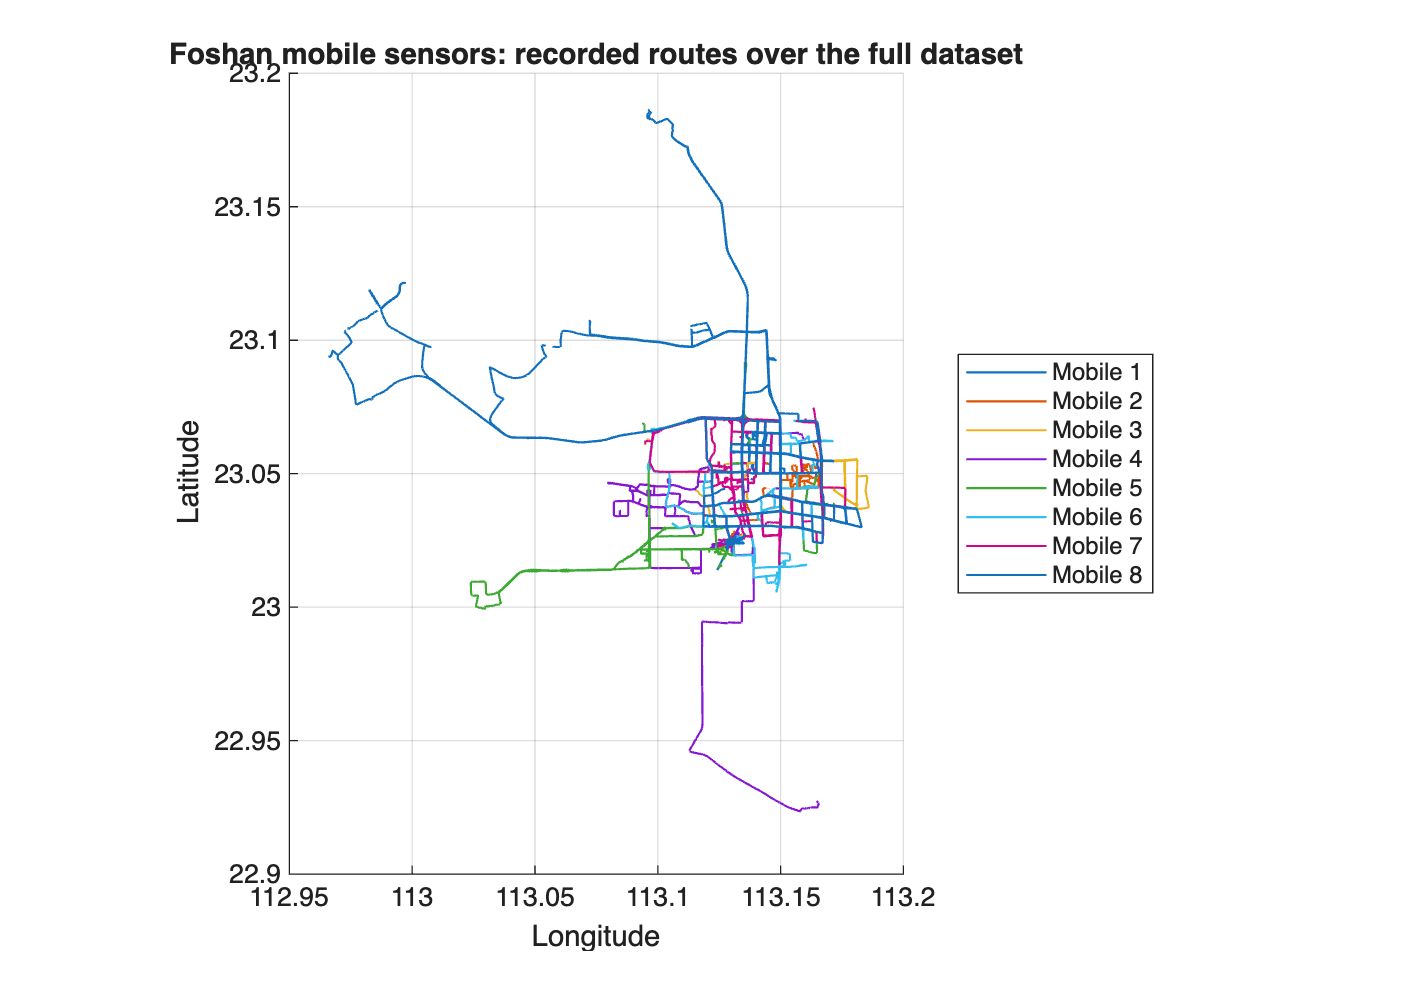


%% Figure 1: All recorded routes together
figure('Color','w', 'Position',[100 100 1000 700]);
hold on;

for i = 1:n
    R = routes{i};

    plot(R.plotLon, R.plotLat, ...
        'Color',colors(i,:), 'LineWidth',0.8, ...
        'DisplayName',char(sensor(i)));
end

grid on;
xlabel('Longitude');
ylabel('Latitude');
title('Foshan mobile sensors: recorded routes over the full dataset');
legend('Location','eastoutside');

% Correct approximate geographic aspect ratio
allLat = cellfun(@(r) mean(r.lat), routes);
daspect([1/cosd(mean(allLat)), 1, 1]);

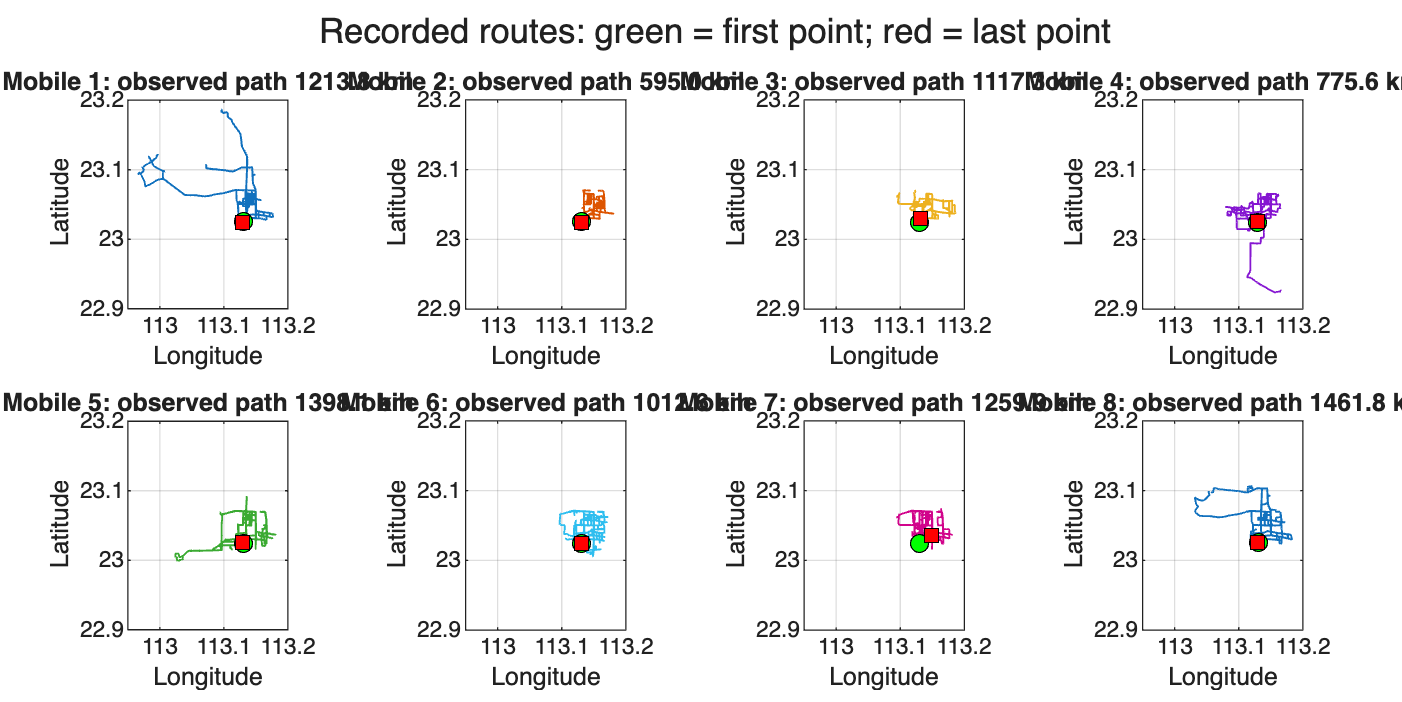


% Use the same map limits in the individual panels
mapX = xlim;
mapY = ylim;

%% Figure 2: Each mobile sensor separately
figure('Color','w', 'Position',[100 100 1400 700]);
tiledlayout(2,4, 'TileSpacing','compact', 'Padding','compact');

for i = 1:n
    R = routes{i};
    nexttile;

    plot(R.plotLon, R.plotLat, ...
        'Color',colors(i,:), 'LineWidth',0.7);
    hold on;

    % Circle = first record; square = last record
    scatter(R.lon(1), R.lat(1), 45, 'g', 'filled', ...
        'MarkerEdgeColor','k');
    scatter(R.lon(end), R.lat(end), 45, 'r', 's', 'filled', ...
        'MarkerEdgeColor','k');

    xlim(mapX);
    ylim(mapY);
    daspect([1/cosd(mean(allLat)), 1, 1]);
    grid on;
    xlabel('Longitude');
    ylabel('Latitude');

    title(sprintf('Mobi
le %d: observed path %.1f km', ...
        i, observedDistanceKm(i)));
end

sgtitle('Recorded routes: green = first point; red = last point');

clear; clc;

S = load('/Users/yuanyang/Downloads/short_term_foshan_train_val.mat', ...
    'data_static', 'data_mobile');

% Typical sampling interval is about 3 seconds.
% Flag intervals > 6 seconds to allow small timing variations.
gapThresholdSeconds = 6;

groups = {'data_static', 'data_mobile'};

allGaps = table('Size', [0 6], ...
    'VariableTypes', ...
    {'string','datetime','datetime','double','double','double'}, ...
    'VariableNames', ...
    {'SensorTable','BeforeGap','AfterGap', ...
    'GapSeconds','GapMinutes','GapHours'});

sensorNames = strings(0,1);
gapCounts = zeros(0,1);
longestGaps = zeros(0,1);
missingTimes = zeros(0,1);
duplicateTimes = zeros(0,1);

for g = 1:numel(groups)
    tables = S.(groups{g});

    for i = 1:numel(tables)
        label = string(sprintf('%s{%d}', groups{g}, i));
        t = tables{i}.time(:);

        numMissingTimes = sum(isnat(t));
        t = sort(t(~isnat(t)));
        numDuplicateTimes = numel(t) - numel(unique(t));

        if numel(t) < 2
            fprintf('%s: fewer than two valid timestamps.\n', label);
            continue;
        end

        dt = seconds(diff(t));
        idx = find(dt > gapThresholdSeconds);

        if ~isempty(idx)
            gaps = table( ...
                repmat(label, numel(idx), 1), ...
                t(idx), ...
                t(idx + 1), ...
                dt(idx), ...
                dt(idx)/60, ...
                dt(idx)/3600, ...
                'VariableNames', allGaps.Properties.VariableNames);

            if isempty(allGaps)
                allGaps = gaps;
            else
                allGaps = [allGaps; gaps];
            end
        end

        sensorNames(end+1,1) = label;
        gapCounts(end+1,1) = numel(idx);
        longestGaps(end+1,1) = max(dt);
        missingTimes(end+1,1) = numMissingTimes;
        duplicateTimes(end+1,1) = numDuplicateTimes;
    end
end

%% Summary for each sensor table
gapSummary = table( ...
    sensorNames, gapCounts, longestGaps, missingTimes, duplicateTimes, ...
    'VariableNames', ...
    {'SensorTable','NumberOfGaps','LongestIntervalSeconds', ...
    'MissingTimestamps','DuplicateTimestamps'});

disp('Summary:');

Summary:


disp(gapSummary);

      SensorTable       NumberOfGaps    LongestIntervalSeconds    MissingTimestamps    DuplicateTimestamps
    ________________    ____________    ______________________    _________________    ___________________

    "data_static{1}"          6                    75                     0                     0         
    "data_static{2}"          7                    72                     0                     0         
    "data_static{3}"          7                    73                     0                     0         
    "data_static{4}"          6                    75                     0                     0         
    "data_static{5}"          9                    72                     0                     0         
    "data_mobile{1}"        208                 41030                     0     


%% All detected gaps, longest first
allGaps = sortrows(allGaps, 'GapSeconds', 'descend');

fprintf('\nTotal intervals longer than %.1f seconds: %d\n', ...
    gapThresholdSeconds, height(allGaps));


Total intervals longer than 6.0 seconds: 2177



disp('Longest 20 gaps:');

Longest 20 gaps:


disp(allGaps(1:min(20, height(allGaps)), :));

      SensorTable            BeforeGap              AfterGap          GapSeconds    GapMinutes    GapHours
    ________________    ___________________    ___________________    __________    __________    ________

    "data_mobile{2}"    2018-10-11 07:06:34    2018-10-12 00:02:32      60958           1016       16.933 
    "data_mobile{1}"    2018-10-14 19:39:46    2018-10-15 07:03:36      41030         683.83       11.397 
    "data_mobile{7}"    2018-10-09 22:58:18    2018-10-10 08:00:39      32541         542.35       9.0392 
    "data_mobile{4}"    2018-10-14 22:46:26    2018-10-15 07:24:21      31075         517.92       8.6319 
    "data_mobile{1}"    2018-10-13 22:09:39    2018-10-14 06:45:50      30971         516.18       8.6031 
    "data_mobile{3}"    2018-10-12 22:48:33   


%% Save complete results
outputFolder = '/Users/yuanyang/Documents/Codex/2026-10-21/he/outputs';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

writetable(allGaps, fullfile(outputFolder, 'foshan_all_gaps.csv'));
writetable(gapSummary, fullfile(outputFolder, 'foshan_gap_summary.csv'));

fprintf('\nCSV files saved to:\n%s\n', outputFolder);


CSV files saved to:
/Users/yuanyang/Documents/Codex/2026-10-21/he/outputs


static_1min = cell(size(S.data_static));

for i = 1:numel(S.data_static)
    T = sortrows(S.data_static{i}, 'time');
    T = T(~isnat(T.time), :);

    TT = table2timetable(T(:, {'time','pm2d5','tmp','hmd'}), ...
        'RowTimes', 'time');

    % average by minute
    A = retime(TT, 'minutely', @(x) mean(x, 'omitnan'));

    % effective PM2.5 data each minute
    N = retime(TT, 'minutely', @(x) sum(~isnan(x)));
    A.n_pm2d5 = N.pm2d5;

    static_1min{i} = A;
end

% the result of the first static sensor
head(static_1min{1})

           time            pm2d5      tmp       hmd      n_pm2d5
    ___________________    ______    ______    ______    _______

    2018-10-08 00:00:00    55.388      34.7    36.983      20   
    2018-10-08 00:01:00     58.65      34.7    36.885      20   
    2018-10-08 00:02:00    60.321      34.7    37.214      19   
    2018-10-08 00:03:00    59.845      34.7    37.237      20   
    2018-10-08 00:04:00     57.15      34.7    37.222      20   
    2018-10-08 00:05:00    59.717      34.7    37.358      20   
    2018-10-08 00:06:00    55.866    34.671    37.255      20   
    2018-10-08 00:07:00     56.35    34.629    37.177      20   



A = static_1min{1};

% One row per minute: 180 rows correspond to 3 hours
lag = 180;

% Predictors: measurements 3 hours earlier and target time of day
targetTime = A.time(lag+1:end);

X = [A.pm2d5(1:end-lag), ...
    A.tmp(1:end-lag), ...
    A.hmd(1:end-lag), ...
    hour(targetTime) + minute(targetTime)/60];

% Target: observed PM2.5
y = A.pm2d5(lag+1:end);

% Train on the first 3 days; validate on the following 3 hours
cutoff = A.time(1) + days(3);

valid = all(isfinite(X), 2) & isfinite(y);
train = valid & targetTime < cutoff;
val = valid & targetTime >= cutoff ...
    & targetTime < cutoff + hours(3);

assert(any(train) && any(val), ...
    'Not enough valid training or validation data.');

% Fit linear regression and predict validation observations
model = fitlm(X(train,:), y(train));
pred = predict(model, X(val,:));

% Persistence: use the last valid PM2.5 before forecasting begins
lastValue = find(A.time < cutoff & isfinite(A.pm2d5), 1, 'last');
baseline = repmat(A.pm2d5(lastValue), sum(val), 1);

fprintf('Linear regression RMSE: %.2f\n', ...
    sqrt(mean((pred - y(val)).^2)));

Linear regression RMSE: 1.78



fprintf('Persistence RMSE: %.2f\n', ...
    sqrt(mean((baseline - y(val)).^2)));

Persistence RMSE: 8.28


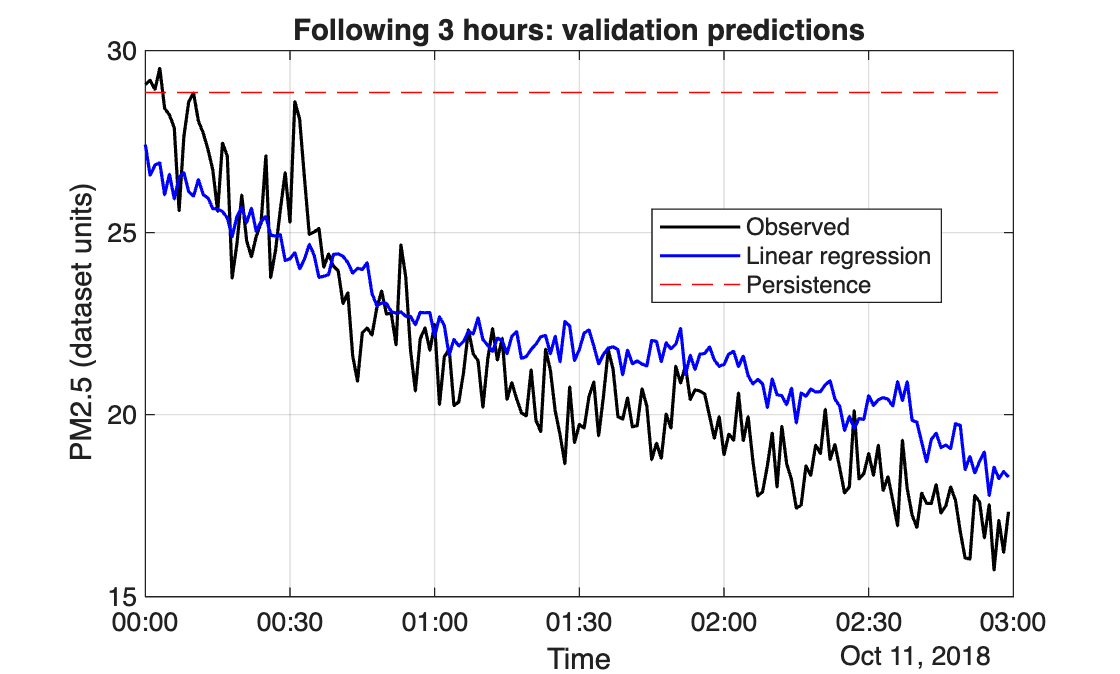


% Compare predictions with observations
figure;
plot(targetTime(val), y(val), 'k', 'LineWidth', 1.2);
hold on;
plot(targetTime(val), pred, 'b', 'LineWidth', 1.2);
plot(targetTime(val), baseline, '--r');

legend('Observed', 'Linear regression', 'Persistence', ...
    'Location', 'best');
xlabel('Time');
ylabel('PM2.5 (dataset units)');
title('Following 3 hours: validation predictions');
grid on;

% Use the existing processed data. No loading required.
A = static_1min{1};
t = A.Properties.RowTimes;

lag = 180;  % Three hours with one-minute data

assert(all(diff(t) == minutes(1)), ...
    'Expected a regular one-minute time grid.');

% Predictors: measurements three hours before each target
targetTime = t(lag+1:end);

X = [A.pm2d5(1:end-lag), ...
     A.tmp(1:end-lag), ...
     A.hmd(1:end-lag), ...
     hour(targetTime) + minute(targetTime)/60];

y = A.pm2d5(lag+1:end);
valid = all(isfinite(X), 2) & isfinite(y);

% Reserve the final day for testing
dataEnd = t(end) + minutes(1);
testStart = dataEnd - days(1);

firstForecast = t(1) + days(3);
lastForecast = testStart - hours(3);

forecastStarts = ...
    (firstForecast:hours(3):lastForecast)';

linearRMSE = NaN(numel(forecastStarts), 1);
persistenceRMSE = NaN(numel(forecastStarts), 1);
nEvaluated = zeros(numel(forecastStarts), 1);

allObserved = [];
allLinear = [];
allPersistence = [];

for k = 1:numel(forecastStarts)
    cutoff = forecastStarts(k);
    trainStart = cutoff - days(3);

    % Training targets and their lagged inputs must both fall
    % within the preceding three days.
    train = valid & ...
        targetTime >= trainStart + hours(3) & ...
        targetTime < cutoff;

    val = valid & ...
        targetTime >= cutoff & ...
        targetTime < cutoff + hours(3);

    if sum(train) < 10 || ~any(val)
        continue;
    end

    model = fitlm(X(train,:), y(train));
    pred = predict(model, X(val,:));

    % Fixed persistence prediction for this entire forecast window
    lastValue = find(t >= trainStart & t < cutoff & ...
        isfinite(A.pm2d5), 1, 'last');

    if isempty(lastValue)
        continue;
    end

    baseline = repmat(A.pm2d5(lastValue), sum(val), 1);
    observed = y(val);

    linearRMSE(k) = sqrt(mean((pred - observed).^2));
    persistenceRMSE(k) = sqrt(mean((baseline - observed).^2));
    nEvaluated(k) = numel(observed);

    allObserved = [allObserved; observed];
    allLinear = [allLinear; pred];
    allPersistence = [allPersistence; baseline];
end

results = table(forecastStarts, nEvaluated, ...
    linearRMSE, persistenceRMSE, ...
    'VariableNames', {'ForecastStart','EvaluatedMinutes', ...
                     'LinearRMSE','PersistenceRMSE'});
disp(results);

       ForecastStart       EvaluatedMinutes    LinearRMSE    PersistenceRMSE
    ___________________    ________________    __________    _______________

    2018-10-11 00:00:00          180             1.7759            8.277    
    2018-10-11 03:00:00          180              2.435           3.2364    
    2018-10-11 06:00:00          180             9.4196           2.9172    
    2018-10-11 09:00:00          180             17.809           7.5837    
    2018-10-11 12:00:00          180             17.125           2.1875    
    2018-10-11 15:00:00          180             9.0968           4.5527    
    2018-10-11 18:00:00          180             7.3868           2.2326    
    2018-10-11 21:00:00          180             4.1075          0.97039    
    2018-10-12 00:00:00          180             9.3474           1.2797    
    2018-10-12 0


assert(~isempty(allObserved), 'No valid windows were evaluated.');

fprintf('Pooled linear regression RMSE: %.2f\n', ...
    sqrt(mean((allLinear - allObserved).^2)));

Pooled linear regression RMSE: 11.50



fprintf('Pooled persistence RMSE: %.2f\n', ...
    sqrt(mean((allPersistence - allObserved).^2)));

Pooled persistence RMSE: 8.00


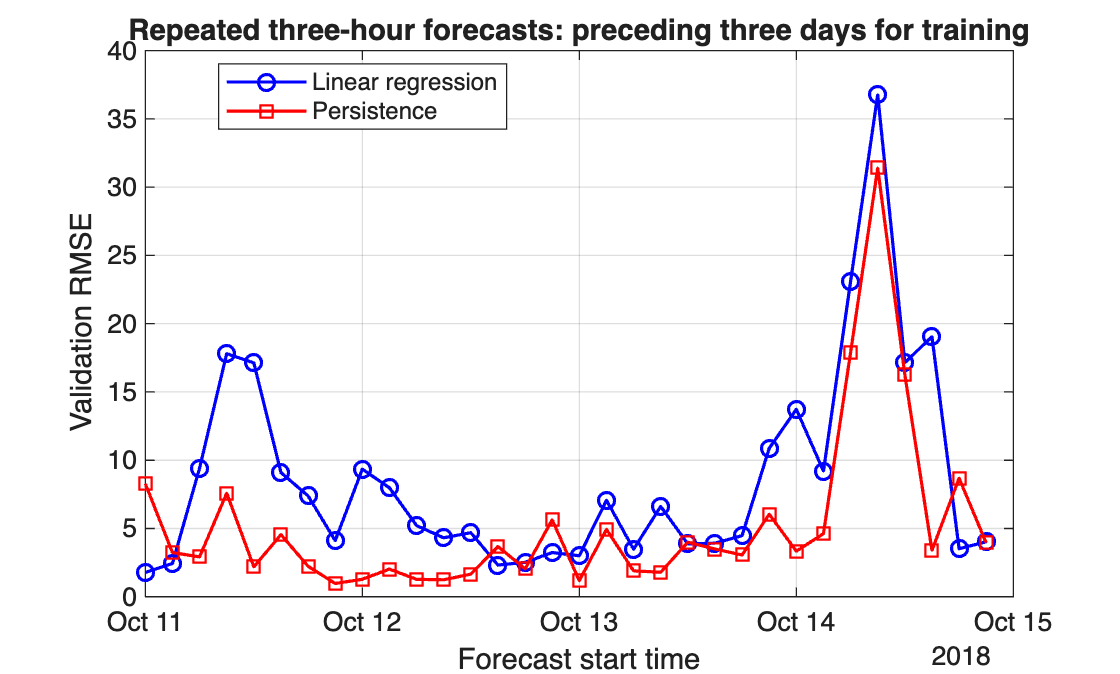


figure;
plot(forecastStarts, linearRMSE, '-ob', 'LineWidth', 1.2);
hold on;
plot(forecastStarts, persistenceRMSE, '-sr', 'LineWidth', 1.2);
xlabel('Forecast start time');
ylabel('Validation RMSE');
legend('Linear regression', 'Persistence', 'Location', 'best');
title('Repeated three-hour forecasts: preceding three days for training');
grid on;

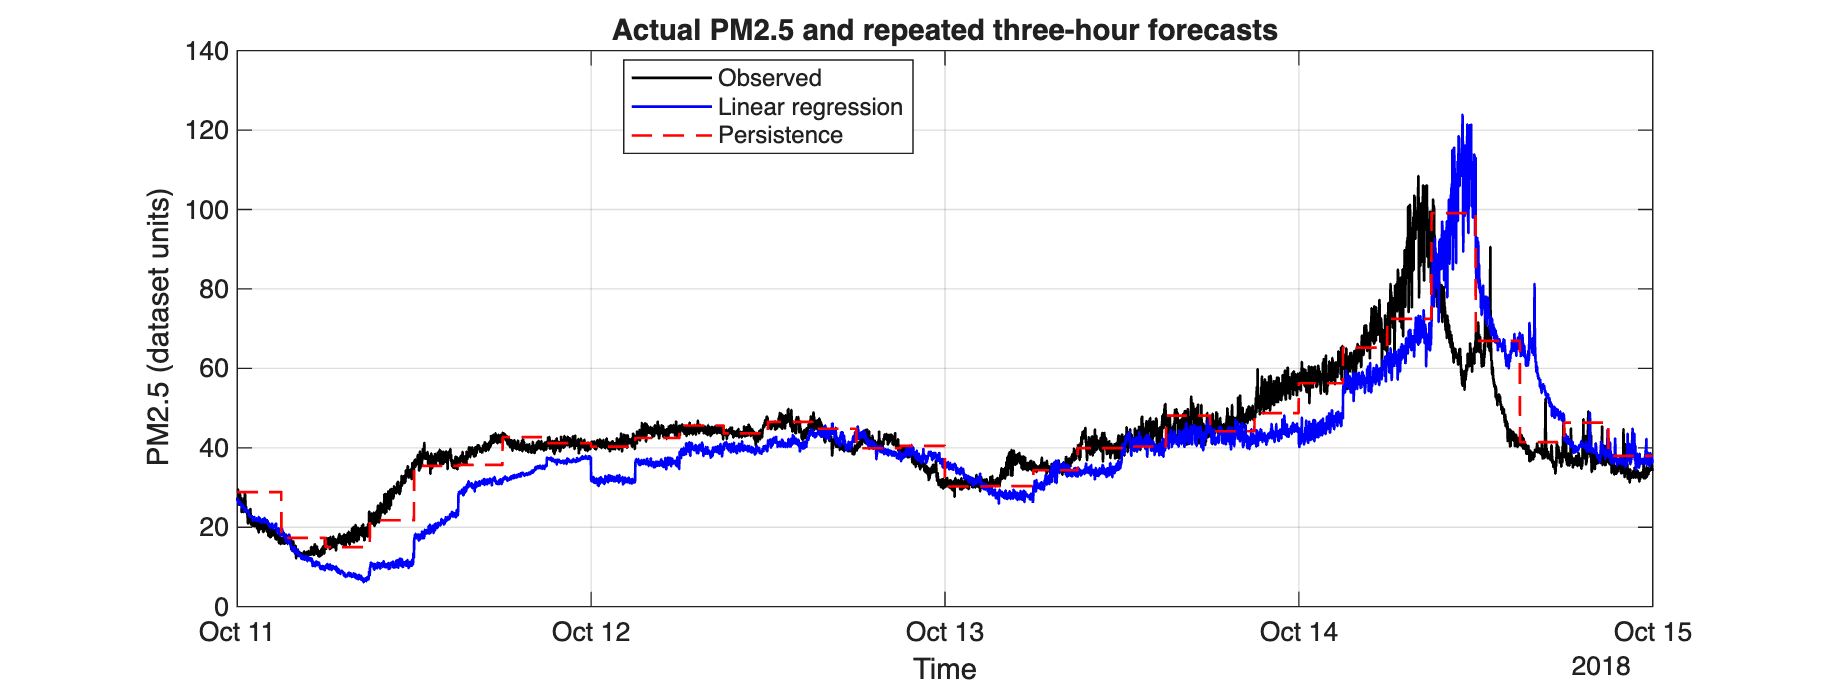

actual = NaN(size(y));
linearPred = NaN(size(y));
persistencePred = NaN(size(y));

for k = 1:numel(forecastStarts)
    cutoff = forecastStarts(k);
    trainStart = cutoff - days(3);

    train = valid & ...
        targetTime >= trainStart + hours(3) & ...
        targetTime < cutoff;

    val = valid & ...
        targetTime >= cutoff & ...
        targetTime < cutoff + hours(3);

    lastValue = find(t >= trainStart & t < cutoff & ...
        isfinite(A.pm2d5), 1, 'last');

    if sum(train) < 10 || ~any(val) || isempty(lastValue)
        continue;
    end

    model = fitlm(X(train,:), y(train));

    actual(val) = y(val);
    linearPred(val) = predict(model, X(val,:));
    persistencePred(val) = A.pm2d5(lastValue);
end

show = targetTime >= firstForecast & targetTime < testStart;

figure('Color','w', 'Position',[100 100 1200 450]);
plot(targetTime(show), actual(show), 'k', 'LineWidth',1);
hold on;
plot(targetTime(show), linearPred(show), 'b', 'LineWidth',1);
plot(targetTime(show), persistencePred(show), '--r', 'LineWidth',1);

xlabel('Time');
ylabel('PM2.5 (dataset units)');
legend('Observed', 'Linear regression', 'Persistence', ...
    'Location','best');
title('Actual PM2.5 and repeated three-hour forecasts');
grid on;